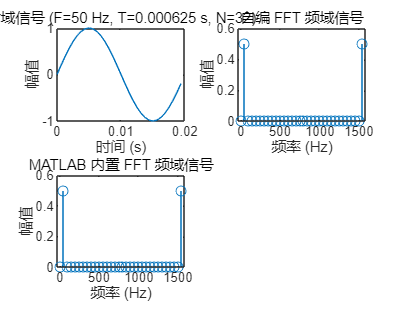

最大差异: 5.463e-15


% 基-2按时间抽取的FFT算法
function X = FFT_time_extract(x)
    N = length(x);
    if N <= 1
        X = x;
    else
        % 递归调用 FFT 计算
        X_even = FFT_time_extract(x(1:2:end));
        X_odd = FFT_time_extract(x(2:2:end));
        W = exp(-2i*pi*(0:N/2-1)/N); % 旋转因子
        X = [X_even + W .* X_odd, X_even - W .* X_odd];
    end
end

% 比较自编FFT与MATLAB内置FFT结果
function compare_fft(F, T, N, zero_padding)
    % 生成信号
    t = (0:N-1) * T;
    x = sin(2*pi*F*t);
    
    % 补零选项
    if zero_padding
        x = [x, zeros(1, N)]; % 补零至2*N样点
        N = 2 * N; % 更新样点数
    end
    
    % 自编FFT
    X_custom = FFT_time_extract(x);
    
    % MATLAB内置FFT
    X_builtin = fft(x);
    
    % 频率轴
    f = (0:N-1) * (1/(N*T));
    
    % 绘制时域图
    figure;
    subplot(2,2,1);
    plot((0:N-1)*T, x);
    title(['时域信号 (F=', num2str(F), ' Hz, T=', num2str(T), ' s, N=', num2str(N), ')']);
    xlabel('时间 (s)');
    ylabel('幅值');

    % 绘制频域比较图
    subplot(2,2,2);
    stem(f, abs(X_custom)/N);
    title('自编 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    subplot(2,2,3);
    stem(f, abs(X_builtin)/N);
    title('MATLAB 内置 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    % 比较结果
    diff = max(abs(X_custom - X_builtin));
    disp(['最大差异: ', num2str(diff)]);
end

% a) F=50Hz, N=32, T=0.000625s
compare_fft(50, 0.000625, 32, 0);

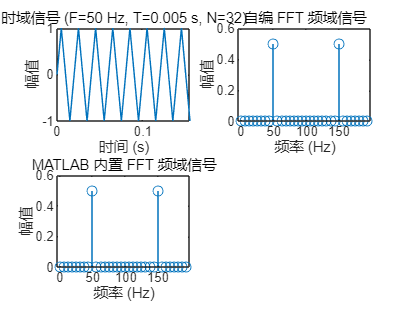

最大差异: 9.7972e-16



% b) F=50Hz, N=32, T=0.005s
compare_fft(50, 0.005, 32, 0);

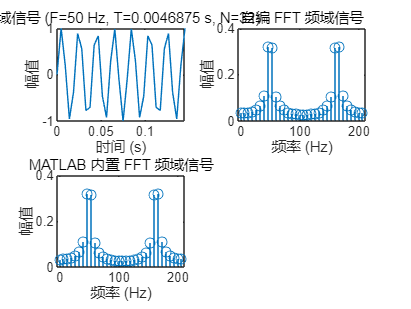

最大差异: 2.5121e-15



% c) F=50Hz, N=32, T=0.0046875s
compare_fft(50, 0.0046875, 32, 0);

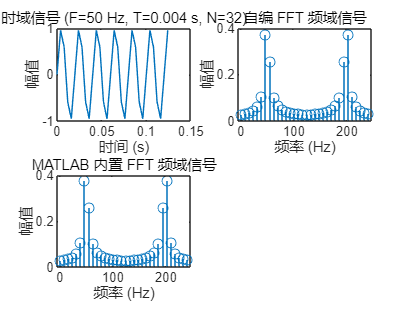

最大差异: 2.5121e-15



% d) F=50Hz, N=32, T=0.004s
compare_fft(50, 0.004, 32, 0);

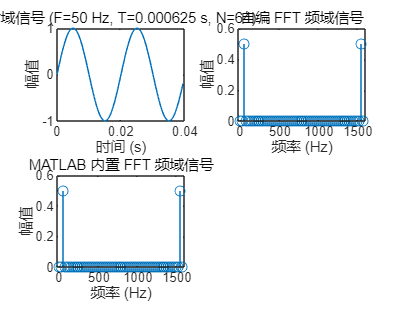

最大差异: 1.1416e-14



% e) F=50Hz, N=64, T=0.000625s
compare_fft(50, 0.000625, 64, 0);

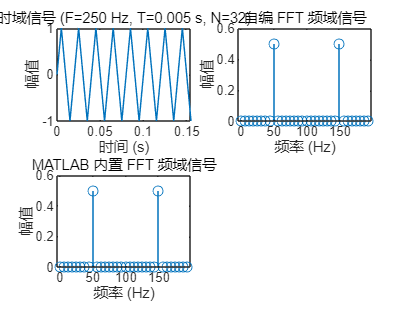

最大差异: 9.7972e-16



% f) F=250Hz, N=32, T=0.005s
compare_fft(250, 0.005, 32, 0);

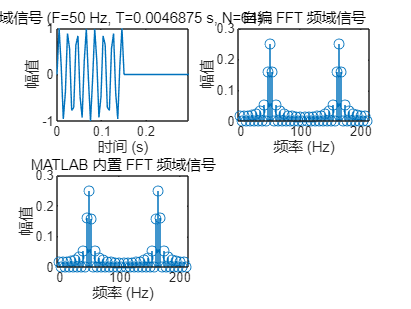

最大差异: 5.8344e-15



% g) F=50Hz, N=32, T=0.0046875s, 补零
compare_fft(50, 0.0046875, 32, 1);